% ============================== TNHS ==============================
% Reports (per data rate):
%   - Delivered                     (packets reaching sink)
%   - AvgQueueDelay_rounds          (avg queue wait, in "rounds" ≈ cycles; non-integer via randomness)
%   - AvgE2EDelay_s                 (queue+link delay, seconds)
%   - FirstDeadRound, AllDeadRound  (over sources)
%   - CompTime_s                    (wall time per rate)
%   - Throughput_Mbps               (delivered * bits / total_time)
%   - RoutingOverhead_ratio         (fraction of delivered using ≥1 relay hop)
%   - Jitter_s                      (std of diffs between consecutive per-packet E2E delays)
%   - Reliability_ratio             (Delivered / Sent)
%   - PacketDropRatio               (Dropped / Sent)
%   - Src*_Eres_J                   (residual energy per source)
% =================================================================================================

clc; clear; rng(42);

%% ----------------------------- USER SETTINGS -----------------------------
outDir = 'C:\Users\saidu\Documents\MATLAB';
if ~exist(outDir,'dir'), mkdir(outDir); end

%% ------------------------------- Parameters ------------------------------
areaSize = 250;                 % cm (2.5m x 2.5m)
numRelays = 7;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink;
range = 50;                     % cm radio/relay range

initialEnergy = 7;              % J
energyThreshold = 0.2 * initialEnergy;

normalTemp = 37;
tempThreshold = 39;             % used for non-critical routing gate
criticalThreshold = 40;         % critical threshold (TNHS focuses on Source 3)

packetBits = 3000;              % bits (align with TAEERS/OLQS)
dataRates = 20:10:100;          % kbps
simTime = 1000;                 % seconds (observation window for throughput)

% Delay model (ms), consistent with TNHS style
queueDelayBase_ms = 5;
queueVar_ms       = 10;
directDistScale_ms_per_cm = 0.1;  % extra delay for direct path per cm

% Energy model (per transmission or reception)
E_tx_direct = 0.1;   % J
E_tx_relay  = 0.05;  % J
E_rx_relay  = 0.05;  % J

% -------- Non-binary behavior helpers (to avoid only 0/1 metrics) ----------
% Per-hop link error (PER) depends on rate & distance; small noise; capped
BASE_PER       = 0.015;
PER_RATE_GAIN  = 0.030;
PER_DIST_GAIN  = 0.050;
PER_NOISE      = 0.010;
PER_MAX_CAP    = 0.35;

% Small, rate-driven queue drop probability (increases with load)
queueDropBase  = 0.010;
queueDropGain  = 0.035;     % scales with (rate/100)

% Occasionally force a relay even when within range (MAC/backoff effects)
prob_force_relay_when_in_range = 0.10;

%% --------------------------- Initialize Nodes ----------------------------
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
sinkID = numNodes;

%% ----------------------------- Load Sensor Data --------------------------
% Expect 8 columns (one per source), TNHS uses temperature from column 3 (BT)
sensorData = readmatrix('DATA.csv');
if size(sensorData,2) ~= numSources
    error('Expected 8 columns of sensor data for 8 source nodes (TNHS).');
end
numCycles = size(sensorData,1);

%% --------------------------- Output (Master Table) -----------------------
% 12 + numSources columns (same layout as TAEERS/OLQS)
AllMetrics = table('Size',[numel(dataRates), 12+numSources], ...
    'VariableTypes', repmat("double",1,12+numSources), ...
    'VariableNames', [ ...
      "DataRate_kbps","Delivered","AvgQueueDelay_rounds","AvgE2EDelay_s", ...
      "FirstDeadRound","AllDeadRound","CompTime_s", ...
      "Throughput_Mbps","RoutingOverhead_ratio","Jitter_s", ...
      "Reliability_ratio","PacketDropRatio", ...
      arrayfun(@(i) sprintf('Src%d_Eres_J',i), 1:numSources, 'UniformOutput', false) ...
    ]);

%% =============================== Simulation ==============================
for rdx = 1:numel(dataRates)
    rate_kbps = dataRates(rdx);

    % Reinitialize per-rate state
    energy   = initialEnergy * ones(numNodes,1);
    nodeDead = false(numNodes,1);

    % Accumulators (TAEERS/OLQS metrics)
    delivered = 0;
    sumQueueRounds = 0;
    sumE2E_s = 0;

    perPacketDelayList_s = [];   % for jitter
    relayedFlags = [];           % 1 if relayed (>=1 relay hop), 0 if direct

    firstDeadRound = NaN;        % among sources only
    allDeadRound   = NaN;        % among sources only

    % Reliability/Drop
    totalPacketsSent    = 0;
    totalPacketsDropped = 0;

    % Injection probability (map kbps -> probability, floor at 0.25)
    p_inject = max(rate_kbps/100, 0.25);

    % Helpers
    per_hop_per = @(hop_cm) min(PER_MAX_CAP, ...
        BASE_PER + PER_RATE_GAIN*(rate_kbps/100) + ...
        PER_DIST_GAIN*max(0, hop_cm)/range + PER_NOISE*rand());
    p_qdrop = min(0.5, queueDropBase + queueDropGain*(rate_kbps/100));

    simtic = tic;

    for t = 1:numCycles
        % Mark source deaths at round start
        srcAliveMask = true(numSources,1);
        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID) || energy(srcID) < energyThreshold
                nodeDead(srcID) = true;
                srcAliveMask(s) = false;
            end
        end
        deadSources = sum(~srcAliveMask);
        if isnan(firstDeadRound) && deadSources > 0, firstDeadRound = t; end
        if isnan(allDeadRound)   && deadSources >= numSources, allDeadRound = t; end
        if deadSources >= numSources, continue; end

        % Each source may inject at most one packet this round
        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID), continue; end
            if rand > p_inject, continue; end

            % Count as SENT when generated
            totalPacketsSent = totalPacketsSent + 1;

            % Temperature value (BT) from column 3
            BT = sensorData(t,3);

            % TNHS critical rule: only Source 3 is critical if BT >= criticalThreshold
            isCritical = (s == 3) && (BT >= criticalThreshold);

            % Queue wait approximation in "rounds" (non-integer; load-sensitive)
            q_noise = 0.5 + rand()*1.5;       % 0.5 .. 2.0
            q_load  = 0.5*(rate_kbps/100);    % 0 .. 0.5
            q_type  = (~isCritical)*0.25;     % 0 or 0.25
            qWait_rounds = q_noise + q_load + q_type;

            % Distance to sink (cm)
            dist_cm = vecnorm(positions(srcID,:) - positions(sinkID,:), 2, 2);

            % Decide path: critical prefer direct when in range unless forced to relay
            in_range = dist_cm <= range;
            force_relay = in_range && (rand < prob_force_relay_when_in_range);
            use_direct = isCritical && in_range && ~force_relay;

            if use_direct
                % Queue drop possibility
                if rand < p_qdrop
                    totalPacketsDropped = totalPacketsDropped + 1;
                    continue;
                end

                % Direct hop: energy & PER
                energy(srcID) = max(0, energy(srcID) - E_tx_direct);
                p_err = per_hop_per(dist_cm);

                if (energy(srcID) < energyThreshold) || (rand < p_err)
                    nodeDead(srcID) = (energy(srcID) < energyThreshold);
                    totalPacketsDropped = totalPacketsDropped + 1;
                else
                    % Delivered
                    linkDelay_ms = (rand()*100) + dist_cm*directDistScale_ms_per_cm;
                    delivered = delivered + 1;
                    sumQueueRounds = sumQueueRounds + qWait_rounds;
                    e2e_s = qWait_rounds + (linkDelay_ms/1000);
                    sumE2E_s = sumE2E_s + e2e_s;
                    perPacketDelayList_s(end+1,1) = e2e_s; %#ok<AGROW>
                    relayedFlags(end+1,1) = 0;           %#ok<AGROW>
                end

            else
                % Non-critical OR critical but (out of range OR forced relay): attempt relay
                dists = vecnorm(positions - positions(srcID,:), 2, 2);
                eligibleRelays = find(dists <= range & roles' == "Relay" & ~nodeDead);

                if isempty(eligibleRelays)
                    totalPacketsDropped = totalPacketsDropped + 1;
                else
                    relayID = eligibleRelays(randi(length(eligibleRelays)));

                    % Queue drop possibility before relay
                    if rand < p_qdrop
                        totalPacketsDropped = totalPacketsDropped + 1;
                        continue;
                    end

                    % Two hops: src->relay and relay->sink
                    hop1_cm = vecnorm(positions(srcID,:)  - positions(relayID,:), 2, 2);
                    hop2_cm = vecnorm(positions(relayID,:)- positions(sinkID,:), 2, 2);

                    % Energy
                    energy(srcID)   = max(0, energy(srcID)   - E_tx_relay);
                    energy(relayID) = max(0, energy(relayID) - E_rx_relay);

                    if energy(srcID) < energyThreshold,  nodeDead(srcID)  = true; end
                    if energy(relayID) < energyThreshold,nodeDead(relayID)= true; end

                    % PER trials on both hops
                    hop1_fail = rand < per_hop_per(hop1_cm);
                    hop2_fail = rand < per_hop_per(hop2_cm);

                    if nodeDead(srcID) || nodeDead(relayID) || hop1_fail || hop2_fail
                        totalPacketsDropped = totalPacketsDropped + 1;
                    else
                        % Delivered (include queue + some processing delay)
                        relayQueue_ms = queueDelayBase_ms + rand()*queueVar_ms;
                        linkDelay_ms  = relayQueue_ms + hop1_cm*directDistScale_ms_per_cm + hop2_cm*directDistScale_ms_per_cm;
                        delivered = delivered + 1;
                        sumQueueRounds = sumQueueRounds + qWait_rounds;
                        e2e_s = qWait_rounds + (linkDelay_ms/1000);
                        sumE2E_s = sumE2E_s + e2e_s;
                        perPacketDelayList_s(end+1,1) = e2e_s; %#ok<AGROW>
                        relayedFlags(end+1,1) = 1;           %#ok<AGROW>
                    end
                end
            end
        end % sources
    end % rounds

    compTime_s = toc(simtic);

    % Fill dead rounds if none occurred
    if isnan(firstDeadRound), firstDeadRound = numCycles; end
    if isnan(allDeadRound),   allDeadRound   = numCycles; end

    % Averages
    if delivered > 0
        avgQ_rounds = sumQueueRounds / delivered;
        avgE2E_s    = sumE2E_s      / delivered;
    else
        avgQ_rounds = 0;
        avgE2E_s    = 0;
    end

    % Throughput (Mbps) over the observation window
    bitsDelivered   = delivered * packetBits;
    Throughput_Mbps = (bitsDelivered / simTime) / 1e6;

    % Routing overhead: fraction of delivered using ≥1 relay hop
    if delivered > 0
        RoutingOverhead_ratio = sum(relayedFlags) / delivered;
    else
        RoutingOverhead_ratio = 0;
    end

    % Jitter: std of successive diffs of per-packet E2E (s)
    if numel(perPacketDelayList_s) >= 2
        Jitter_s = std(diff(perPacketDelayList_s));
    else
        Jitter_s = 0;
    end

    % Reliability & Drop
    if totalPacketsSent > 0
        Reliability_ratio = delivered / totalPacketsSent;
        PacketDropRatio   = totalPacketsDropped / totalPacketsSent;
    else
        Reliability_ratio = 0;
        PacketDropRatio   = 0;
    end

    % Residual energy per source (J)
    for s = 1:numSources
        srcID = numRelays + s;
        AllMetrics.(sprintf('Src%d_Eres_J', s))(rdx) = energy(srcID);
    end

    % Store
    AllMetrics.DataRate_kbps(rdx)         = rate_kbps;
    AllMetrics.Delivered(rdx)             = delivered;
    AllMetrics.AvgQueueDelay_rounds(rdx)  = avgQ_rounds;
    AllMetrics.AvgE2EDelay_s(rdx)         = avgE2E_s;
    AllMetrics.FirstDeadRound(rdx)        = firstDeadRound;
    AllMetrics.AllDeadRound(rdx)          = allDeadRound;
    AllMetrics.CompTime_s(rdx)            = compTime_s;
    AllMetrics.Throughput_Mbps(rdx)       = Throughput_Mbps;
    AllMetrics.RoutingOverhead_ratio(rdx) = RoutingOverhead_ratio;
    AllMetrics.Jitter_s(rdx)              = Jitter_s;
    AllMetrics.Reliability_ratio(rdx)     = Reliability_ratio;
    AllMetrics.PacketDropRatio(rdx)       = PacketDropRatio;

    % Console summary
    fprintf(['TNHS rate=%3d kbps | Sent=%5d | Delivered=%5d | AvgE2E=%.4f s | Thrpt=%.6f Mbps | ' ...
             'Overhead=%.3f | Jitter=%.6f s | Rel=%.3f | Drop=%.3f | ' ...
             'FirstDead=%d | AllDead=%d | Time=%.2fs\n'], ...
        rate_kbps, totalPacketsSent, delivered, avgE2E_s, Throughput_Mbps, ...
        RoutingOverhead_ratio, Jitter_s, Reliability_ratio, PacketDropRatio, ...
        firstDeadRound, allDeadRound, compTime_s);
end

TNHS rate= 20 kbps | Sent=25474 | Delivered=  464 | AvgE2E=1.6387 s | Thrpt=0.001392 Mbps | Overhead=1.000 | Jitter=0.608100 s | Rel=0.018 | Drop=0.982 | FirstDead=399 | AllDead=20000 | Time=0.49s
TNHS rate= 30 kbps | Sent=30142 | Delivered=  488 | AvgE2E=1.6830 s | Thrpt=0.001464 Mbps | Overhead=1.000 | Jitter=0.599207 s | Rel=0.016 | Drop=0.984 | FirstDead=366 | AllDead=20000 | Time=0.19s
TNHS rate= 40 kbps | Sent=40593 | Delivered=  492 | AvgE2E=1.7051 s | Thrpt=0.001476 Mbps | Overhead=1.000 | Jitter=0.582175 s | Rel=0.012 | Drop=0.988 | FirstDead=287 | AllDead=20000 | Time=0.28s
TNHS rate= 50 kbps | Sent=50484 | Delivered=  482 | AvgE2E=1.7695 s | Thrpt=0.001446 Mbps | Overhead=1.000 | Jitter=0.565111 s | Rel=0.010 | Drop=0.990 | FirstDead=211 | AllDead=20000 | Time=0.35s
TNHS rate= 60 kbps | Sent=60267 | Delivered=  487 | AvgE2E=1.8123 s | Thrpt=0.001461 Mbps | Overhead=1.000 | Jitter=0.657311 s | Rel=0.008 | Drop=0.992 | FirstDead=186 | AllDead=20000 | Time=0.36s
TNHS rate= 70 k


%% ------------------------------- Save CSVs --------------------------------
% Master
writetable(AllMetrics, fullfile(outDir,'tnhs_metrics_by_rate.csv'));

% Per-metric (TAEERS/OLQS-style; TNHS suffix for clarity)
writetable(AllMetrics(:, {'DataRate_kbps','AvgE2EDelay_s'}),                  fullfile(outDir,'e2e_delay_by_rate_tnhs.csv'));
writetable(AllMetrics(:, {'DataRate_kbps','AvgQueueDelay_rounds'}),           fullfile(outDir,'queueing_delay_by_rate_tnhs.csv'));
writetable(AllMetrics(:, {'DataRate_kbps','FirstDeadRound','AllDeadRound'}),  fullfile(outDir,'network_lifetime_by_rate_tnhs.csv'));

resCols = [{'DataRate_kbps'}, arrayfun(@(i) sprintf('Src%d_Eres_J',i), 1:numSources, 'UniformOutput', false)];
writetable(AllMetrics(:, resCols),                                            fullfile(outDir,'residual_energy_by_rate_tnhs.csv'));

writetable(AllMetrics(:, {'DataRate_kbps','CompTime_s'}),                     fullfile(outDir,'computational_time_by_rate_tnhs.csv'));
writetable(AllMetrics(:, {'DataRate_kbps','Throughput_Mbps'}),                fullfile(outDir,'throughput_by_rate_tnhs.csv'));
writetable(AllMetrics(:, {'DataRate_kbps','RoutingOverhead_ratio'}),          fullfile(outDir,'routing_overhead_by_rate_tnhs.csv'));
writetable(AllMetrics(:, {'DataRate_kbps','Jitter_s'}),                       fullfile(outDir,'jitter_by_rate_tnhs.csv'));
writetable(AllMetrics(:, {'DataRate_kbps','Reliability_ratio'}),              fullfile(outDir,'reliability_by_rate_tnhs.csv'));
writetable(AllMetrics(:, {'DataRate_kbps','PacketDropRatio'}),                fullfile(outDir,'packet_drop_ratio_by_rate_tnhs.csv'));

disp('✅ TNHS simulation completed: full TAEERS/OLQS-style metrics (incl. reliability & drop) saved to output directory.');

✅ TNHS simulation completed: full TAEERS/OLQS-style metrics (incl. reliability & drop) saved to output directory.


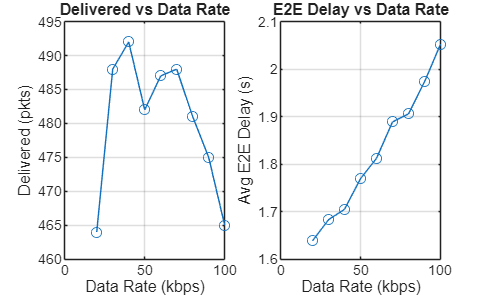


%% -------------------------------- Plots (quick) ---------------------------
figure('Name','TNHS: Delivered & E2E vs Data Rate');
subplot(1,2,1); plot(AllMetrics.DataRate_kbps, AllMetrics.Delivered,'-o'); grid on;
xlabel('Data Rate (kbps)'); ylabel('Delivered (pkts)'); title('Delivered vs Data Rate');
subplot(1,2,2); plot(AllMetrics.DataRate_kbps, AllMetrics.AvgE2EDelay_s,'-o'); grid on;
xlabel('Data Rate (kbps)'); ylabel('Avg E2E Delay (s)'); title('E2E Delay vs Data Rate');

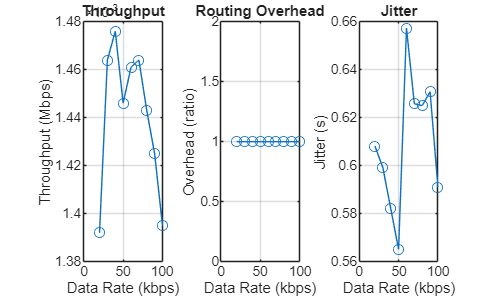


figure('Name','TNHS: Throughput / Overhead / Jitter');
subplot(1,3,1); plot(AllMetrics.DataRate_kbps, AllMetrics.Throughput_Mbps,'-o'); grid on;
xlabel('Data Rate (kbps)'); ylabel('Throughput (Mbps)'); title('Throughput');
subplot(1,3,2); plot(AllMetrics.DataRate_kbps, AllMetrics.RoutingOverhead_ratio,'-o'); grid on;
xlabel('Data Rate (kbps)'); ylabel('Overhead (ratio)'); title('Routing Overhead');
subplot(1,3,3); plot(AllMetrics.DataRate_kbps, AllMetrics.Jitter_s,'-o'); grid on;
xlabel('Data Rate (kbps)'); ylabel('Jitter (s)'); title('Jitter');

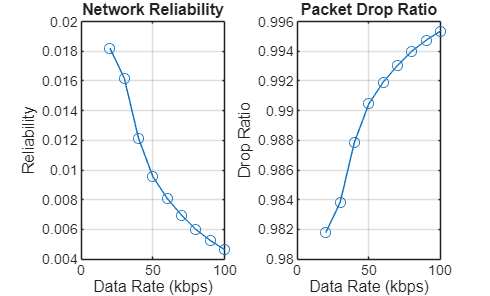


figure('Name','TNHS: Reliability & Drop Ratio');
subplot(1,2,1); plot(AllMetrics.DataRate_kbps, AllMetrics.Reliability_ratio,'-o'); grid on;
xlabel('Data Rate (kbps)'); ylabel('Reliability'); title('Network Reliability');
subplot(1,2,2); plot(AllMetrics.DataRate_kbps, AllMetrics.PacketDropRatio,'-o'); grid on;
xlabel('Data Rate (kbps)'); ylabel('Drop Ratio'); title('Packet Drop Ratio');

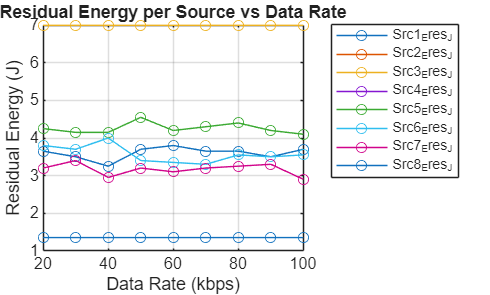


figure('Name','TNHS: Residual Energy per Source');
R = AllMetrics{:, startsWith(AllMetrics.Properties.VariableNames,'Src') & endsWith(AllMetrics.Properties.VariableNames,'_Eres_J')};
plot(AllMetrics.DataRate_kbps, R, '-o'); grid on;
xlabel('Data Rate (kbps)'); ylabel('Residual Energy (J)');
title('Residual Energy per Source vs Data Rate');
legend(AllMetrics.Properties.VariableNames( ...
    startsWith(AllMetrics.Properties.VariableNames,'Src') & endsWith(AllMetrics.Properties.VariableNames,'_Eres_J')), ...
    'Location','bestoutside');